## Draw the picture

Leader_pos = x;

[x_size,y_size] =size(Leader_pos);

AC_D = Leader_pos(1:y_size-4);
AS_D = Leader_pos(y_size-3:y_size);

 ACT=[   a1,a2,a3,a4,a5;
        
          ];
 AST=[   a6,a7,a8,a9;
       
        ];

M=0.06;
NDIS=100;
DISR = 0;

NTU=9;
NTERM=(NTU-1)/2;

H=2.*pi/real(NDIS-1);
for I=1:NDIS
           SM=H*(I-1);
           FR=0;
           FF=0;

         for II=1:NTERM
             FF=ACT(II+1)*cos(II*SM)+AST(II)*sin(II*SM)+FF;
             FR=AC_D(II+1)*cos(II*SM)+AS_D(II)*sin(II*SM)+FR;
         end
           FF=ACT(1)+FF;
           FR=AC_D(1)+FR;
           DISR=((FR-FF)/FR).^2/NDIS+DISR;

           X(I)=FR*cos(SM);
           Y(I)=FR*sin(SM);
           x1(I)=FF*cos(SM);
           y1(I)=FF*sin(SM);
end

DISR = sqrt(DISR)*100 

DISR = 7.7023e-05

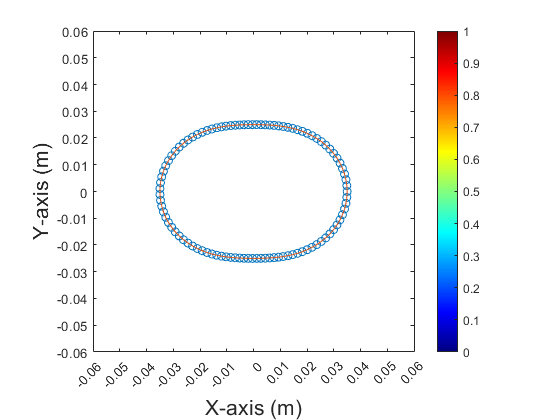


plot(X,Y,'o',x1,y1);

C=[0 1];
axis square;
colormap(jet);colorbar;
xlabel('X-axis (m)','fontsize',16);
ylabel('Y-axis (m)','fontsize',16);
grid off 
set(gca,'xtick',[-M:0.01:M])
set(gca,'ytick',[-M:0.01:M])
yticklabels([-M:0.01:M]);
% colormapeditor;
axis([-M M -M M]); 


D = duration(0,0,toc,'Format','hh:mm:ss');

Error using toc
You must call TIC without an output argument before calling TOC without an input argument.

title(...
"Iteration: " + t + ", " + ...
"time: " + string(D))